addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Integration'))

Trapezoidal rule

f = @(x) sin(x)

f = function_handle with value:
    @(x)sin(x)


[ss, hs] = trapezoidIter(f, 0, pi);

Solution with     2 intervals is   1.570796327
Solution with     4 intervals is   1.896118898
Solution with     8 intervals is   1.974231602
Solution with    16 intervals is   1.993570344
Solution with    32 intervals is   1.998393361
Solution with    64 intervals is   1.999598389
Solution with   128 intervals is   1.999899600
Solution with   256 intervals is   1.999974900
Solution with   512 intervals is   1.999993725
Solution with  1024 intervals is   1.999998431
Solution with  2048 intervals is   1.999999608
Solution with  4096 intervals is   1.999999902
Solution with  8192 intervals is   1.999999975
Solution with 16384 intervals is   1.999999994
Solution with 32768 intervals is   1.999999998
Solution with 65536 intervals is   2.000000000


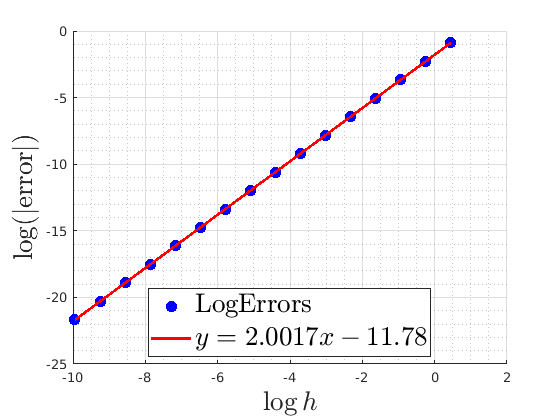

plotLogErrorIntegr(ss, hs, 2) % slope = 2 so quadratic

% error convergence is evidence. 

f = @(x) exp(-x.^2) - exp(-4*x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)-exp(-4*x.^2)


[ss, hs] = trapezoidIter(f, 1, 2);

Solution with     2 intervals is   0.144607740
Solution with     4 intervals is   0.135915562
Solution with     8 intervals is   0.133859072
Solution with    16 intervals is   0.133352628
Solution with    32 intervals is   0.133226498
Solution with    64 intervals is   0.133194996
Solution with   128 intervals is   0.133187122
Solution with   256 intervals is   0.133185154
Solution with   512 intervals is   0.133184661
Solution with  1024 intervals is   0.133184538
Solution with  2048 intervals is   0.133184508
Solution with  4096 intervals is   0.133184500
Solution with  8192 intervals is   0.133184498
Solution with 16384 intervals is   0.133184498
Solution with 32768 intervals is   0.133184497
Solution with 65536 intervals is   0.133184497


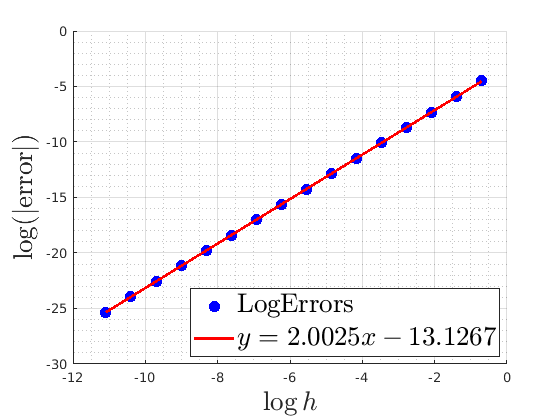

plotLogErrorIntegr(ss, hs, integral(f, 1, 2)) % slope =2

% so quadratic error convergence. 

Simpson rule

f = @(x) sin(x)

f = function_handle with value:
    @(x)sin(x)


[ss, hs] = simpsonIter(f, 0, pi); % more accurate

Solution with     2 intervals =   2.094395102
Solution with     4 intervals =   2.004559755
Solution with     8 intervals =   2.000269170
Solution with    16 intervals =   2.000016591
Solution with    32 intervals =   2.000001033
Solution with    64 intervals =   2.000000065
Solution with   128 intervals =   2.000000004
Solution with   256 intervals =   2.000000000
Solution with   512 intervals =   2.000000000
Solution with  1024 intervals =   2.000000000
Solution with  2048 intervals =   2.000000000
Solution with  4096 intervals =   2.000000000
Solution with  8192 intervals =   2.000000000
Solution with 16384 intervals =   2.000000000
Solution with 32768 intervals =   2.000000000
Solution with 65536 intervals =   2.000000000


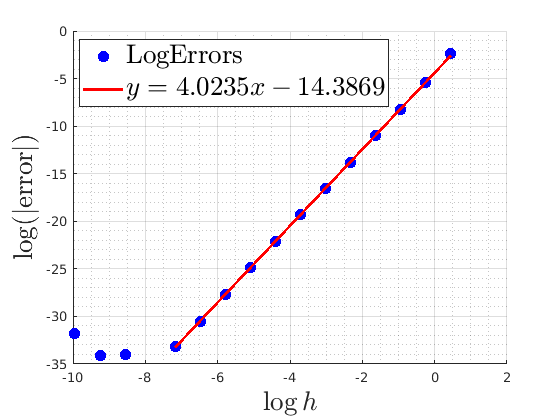

plotLogErrorIntegr(ss, hs, 2) %slope = 4 so shows

% that simpson errors converge to 0 with order 4. 

f = @(x) exp(-x.^2) - exp(-4*x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)-exp(-4*x.^2)


[ss, hs] = simpsonIter(f, 1, 2);

Solution with     2 intervals =   0.131497098
Solution with     4 intervals =   0.133018170
Solution with     8 intervals =   0.133173576
Solution with    16 intervals =   0.133183814
Solution with    32 intervals =   0.133184455
Solution with    64 intervals =   0.133184495
Solution with   128 intervals =   0.133184497
Solution with   256 intervals =   0.133184497
Solution with   512 intervals =   0.133184497
Solution with  1024 intervals =   0.133184497
Solution with  2048 intervals =   0.133184497
Solution with  4096 intervals =   0.133184497
Solution with  8192 intervals =   0.133184497
Solution with 16384 intervals =   0.133184497
Solution with 32768 intervals =   0.133184497
Solution with 65536 intervals =   0.133184497


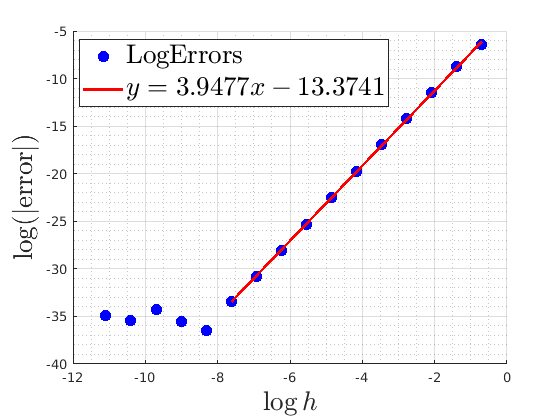

plotLogErrorIntegr(ss, hs, integral(f, 1,2))

Efficient trapezoid and simpson

f = @(x) exp(-x.^2) - exp(-4*x.^2)

f = function_handle with value:
    @(x)exp(-x.^2)-exp(-4*x.^2)



trapezoidIter(f, 1, 2);

Solution with     2 intervals is   0.144607740
Solution with     4 intervals is   0.135915562
Solution with     8 intervals is   0.133859072
Solution with    16 intervals is   0.133352628
Solution with    32 intervals is   0.133226498
Solution with    64 intervals is   0.133194996
Solution with   128 intervals is   0.133187122
Solution with   256 intervals is   0.133185154
Solution with   512 intervals is   0.133184661
Solution with  1024 intervals is   0.133184538
Solution with  2048 intervals is   0.133184508
Solution with  4096 intervals is   0.133184500
Solution with  8192 intervals is   0.133184498
Solution with 16384 intervals is   0.133184498
Solution with 32768 intervals is   0.133184497
Solution with 65536 intervals is   0.133184497
Elapsed time is 0.145648 seconds.


trapezoidIntegrateNBound(f, 1, 2);

Solution with 2^20 intervals = 1048576 equals area 0.133184497436
Elapsed time is 1.670039 seconds.



simpsonIntegrateNBound(f, 1,2);

Solution with 2^11 intervals (2048) is equal to = 0.133184497436 
Elapsed time is 0.004703 seconds.


f = @(x) cos(x.^2)

f = function_handle with value:
    @(x)cos(x.^2)



trapezoidIntegrateNBound(f, 1, 2);

Solution with 2^21 intervals = 2097152 equals area -0.443062775467
Elapsed time is 2.959772 seconds.


simpsonIntegrateNBound(f, 1,2);

Solution with 2^11 intervals (2048) is equal to = -0.443062775467 
Elapsed time is 0.006242 seconds.


f = @(x) (1/sqrt(2*pi))*exp(-0.5*x.^2)

f = function_handle with value:
    @(x)(1/sqrt(2*pi))*exp(-0.5*x.^2)



trapezoidIntegrateNBound(f, -2, 2);

Solution with 2^20 intervals = 1048576 equals area 0.954499736103
Elapsed time is 1.211307 seconds.


simpsonIntegrateNBound(f, -2,2);

Solution with 2^11 intervals (2048) is equal to = 0.954499736104 
Elapsed time is 0.004169 seconds.


f = @(x) 

trapezoidIntegrateNBound(f, -2, 2);
simpsonIntegrateNBound(f, -2,2);